Limpar 

close all
clear
clc

# Lab 03 

## ETAPA 1

Figura 1- Circuito da etapa 1.

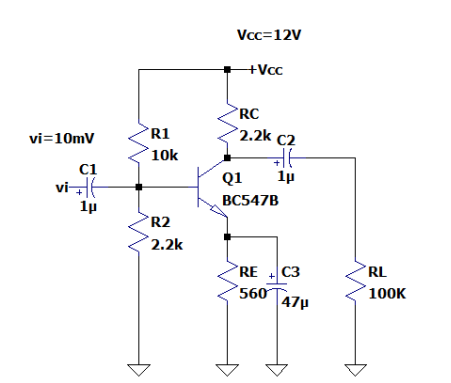

## ** Calc Analise CC (DC)**

Figura 2- Circuito equivalente para analise CC

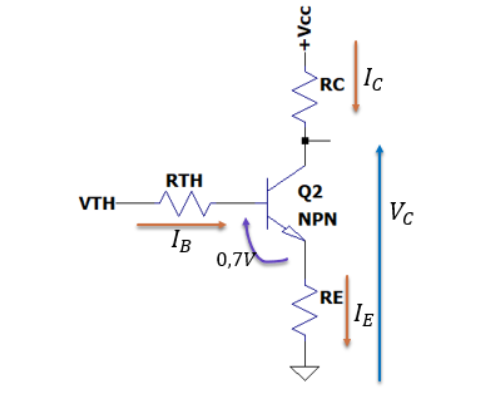

### Valores dos componentes:

R1 = 10e+3;%%Rth
R2 =2.2e+3;%%Rth
RE = 560;%% R2+R3
Vcc = 12;%%Variavel de entrada
B = 290; % Beta para o calc
Vbe = 0.7; 
Vce = 5; %data sheet


### Equivalentes de TH

Vth = (R2/(R1+R2))*Vcc

Vth = 2.1639

Rth = ((1/R1)+(1/R2))^-1

Rth = 1.8033e+03

### Correntes

Ib = (Vth-Vbe)/(Rth+RE*(B+1))

Ib = 8.8851e-06

%%Ib = Vth/(Rth+RE*B+2*RE)%%Ib = (Vth-Vbe)/(Rth+RE*(B+1)) %%12e-6%%
Ie = (B+1)*Ib

Ie = 0.0026

## **Calc Analise CA (AC)**

Figura 3- Circuito equivalente para analise CA

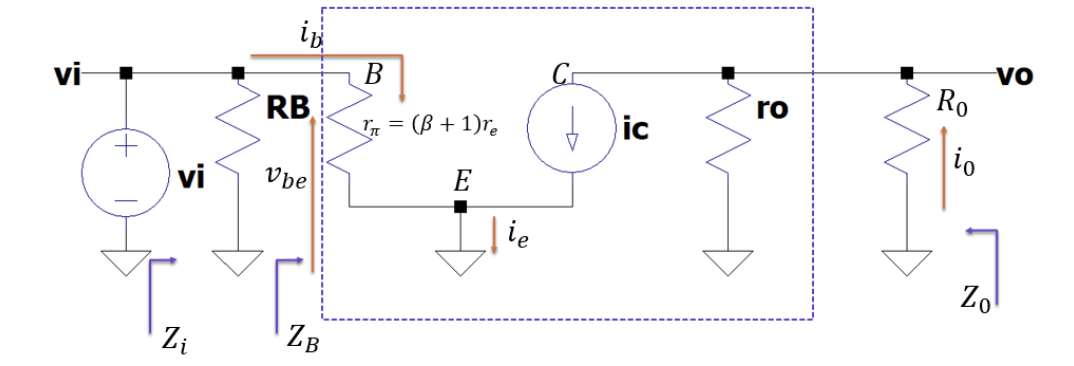

### Valores dos componentes 

*Obs.: todos os valores de componentes possuem a variavel com nome correspondente ao circuito apresentado na figura 1.

RL = 100e+3;%% 16%valor de entrada da figura 1
RC = 2.2e+3;%valor de entrada da figura 1
RB = Rth; %calculado
R0 = ((1/RL)+(1/RC))^-1%calculado R0

R0 = 2.1526e+03

VT = 25e-3%%1.38e-23*((273+25)/1.6e-19)%%22e-3 Tensão termica dado no datasheet VT = (K*T)/q

VT = 0.0250

vi = 10e-3

vi = 0.0100

### calculo do re e rpi:

re = VT/Ie

re = 9.6691

rpi = (B+1)*re

rpi = 2.8137e+03

**Calculo para CA**

ib = vi/rpi

ib = 3.5540e-06

ic = B*ib

ic = 0.0010

ie = ic

ie = 0.0010

v0 = ic*R0

v0 = 2.2187

Av1 = v0/vi

Av1 = 221.8661

Av = -R0/re

Av = -222.6312